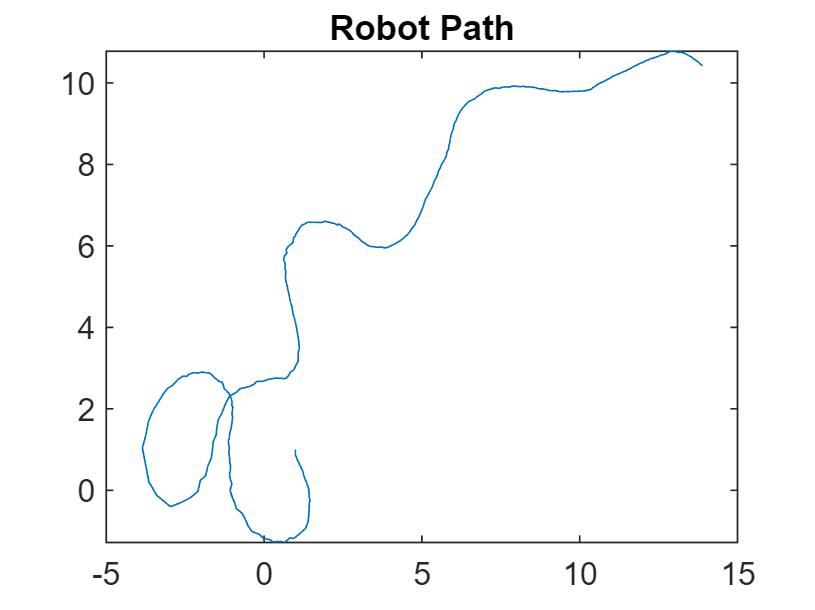

clear,clc;

load("my_input.mat"); % linear velocity input (v), angular velocity input (om), time-vector (t)
load("my_measurements.mat"); % range measurement(r), bearing measurement (b), position of 6 landmarks in xy coordinate (l)

%H Measurement function(non-linear) inputs range and bearing of LIDAR
%the parameters r and b are in the measurement file
%creating a function to call later

%variance of input data
velo_var = 0.01; %sigma v, linear velocity
ang_var = 0.25; %sigma omega, angular velocity
r_1_to_3_var = 0.01; %sigma landmarks 1 to 3
r_4_to_6_var = 0.09; %sigma landmarks 4 to 6
bearing_var = 0.25; %sigma bearing

%initial robot coords
%initial state vector [x,y,theta]'
x = zeros(3,length(t));
%initial state vector
x(:,1) = [1 1 0]'; %initializing x

%%Prediction Step
p = zeros([3,3,length(t)]);
%initial state vector to provide uncertainty
p(:,:,1) = diag([1e-2 1e-2 1e-2]);

%System transition matrix
I = eye(3,3);

%%process noise covariance, Q
noise_value = 0.5;
Q = diag([velo_var, ang_var]) * noise_value;

%%measurement noise covariance, R
R_noise = 15;
R = diag([r_1_to_3_var, bearing_var, ...
     r_1_to_3_var, bearing_var, ...
     r_1_to_3_var, bearing_var, ...
     r_4_to_6_var, bearing_var, ...
     r_4_to_6_var, bearing_var, ...
     r_4_to_6_var, bearing_var]) * R_noise;
%R_k_minus_1 = diag(R); 

%time step
dt = 0.1;

%atan2(y_l, x_l) - theta_k

%this outputs all the ranges first and then all the bearing angles:
%h_nl = @(x, l) [sqrt((l(:,1) - x(1)).^2 + (l(:,2) - x(2)).^2);wrapToPi(atan2(l(:,2)-x(2), l(:,1)-x(1))) - x(3)];

% this outputs the ranges and bearing angles alternated:
 h_nl = @(x, l) [sqrt((l(1,1) - x(1,:)).^2 + (l(1,2) - x(2,:)).^2);
                 wrapToPi(atan2(l(1,2)-x(2,:), l(1,1)-x(1,:))) - x(3,:);
                 sqrt((l(2,1) - x(1,:)).^2 + (l(2,2) - x(2,:)).^2);
                 wrapToPi(atan2(l(2,2)-x(2,:), l(2,1)-x(1,:))) - x(3,:);
                 sqrt((l(3,1) - x(1,:)).^2 + (l(3,2) - x(2,:)).^2);
                 wrapToPi(atan2(l(3,2)-x(2,:), l(3,1)-x(1,:))) - x(3,:);
                 sqrt((l(4,1) - x(1,:)).^2 + (l(4,2) - x(2,:)).^2);
                 wrapToPi(atan2(l(4,2)-x(2,:), l(4,1)-x(1,:))) - x(3,:);
                 sqrt((l(5,1) - x(1,:)).^2 + (l(5,2) - x(2,:)).^2);
                 wrapToPi(atan2(l(5,2)-x(2,:), l(5,1)-x(1,:))) - x(3,:);
                 sqrt((l(6,1) - x(1,:)).^2 + (l(6,2) - x(2,:)).^2);
                 wrapToPi(atan2(l(6,2)-x(2,:), l(6,1)-x(1,:))) - x(3,:)];


ChiStat = zeros(1, length(t));
%%EKF algorithm
for k = 2:length(t)
    %jacobian state matrix without noise (A or F)
    F = [1 , 0, dt*(-v(1, k-1).*sin(x(3, k-1)));
         0, 1, dt*(v(1, k-1).*cos(x(3, k-1)));
         0, 0, 1];
    %Tau or Gamma or weird T
    tau = [dt*cos(x(3,k-1)), 0;
           dt*sin(x(3, k-1)), 0;
           0, dt];
    %Measurements initialisation
    z = [r(k-1,1)'; b(k-1,1)'; r(k-1,2)'; b(k-1,2)';r(k-1,3)';b(k-1,3)';r(k-1,4)';b(k-1,4)';
         r(k-1,5)';b(k-1,5)';r(k-1,6)'; b(k-1,6)'];

    %%Equation 1: state propagation
    xa = I*x(:, k-1) + tau*[v(1,k-1); om(1, k-1)];

    %Equation 2: State covariance propagation
    Pa = F*p(:,:, k-1)*F' + tau*Q*tau';

    %%Measurement Update
    za = h_nl(xa, l); %predicted measurements

    %H matrix
    H = [-(cos(b(k-1,1) + xa(3,1))), -(sin(b(k-1,1) + xa(3,1))), 0;
         (sin(b(k-1,1) + xa(3,1)))/(r(k-1,1)), -(cos(b(k-1,1) + xa(3,1)))/r(k-1,1), -1;
         -(cos(b(k-1,2) + xa(3,1))),-(sin(b(k-1,2) + xa(3,1))), 0;
         (sin(b(k-1,2) + xa(3,1)))/(r(k-1,2)), -(cos(b(k-1,2) + xa(3,1)))/r(k-1,2), -1;
         -(cos(b(k-1,3) + xa(3,1))), -(sin(b(k-1,3) + xa(3,1))), 0;
         (sin(b(k-1,3) + xa(3,1)))/(r(k-1,3)), -(cos(b(k-1,3) + xa(3,1)))/r(k-1,3), -1;
         -(cos(b(k-1,4) + xa(3,1))), -(sin(b(k-1,4) + xa(3,1))), 0;
         (sin(b(k-1,4) + xa(3,1)))/(r(k-1,4)), -(cos(b(k-1,4) + xa(3,1)))/r(k-1,4), -1;      
         -(cos(b(k-1,5) + xa(3,1))), -(sin(b(k-1,5) + xa(3,1))), 0;
         (sin(b(k-1,5) + xa(3,1)))/(r(k-1,5)), -(cos(b(k-1,5) + xa(3,1)))/r(k-1,5), -1;
         -(cos(b(k-1,6) + xa(3,1))), -(sin(b(k-1,6) + xa(3,1))), 0;
         (sin(b(k-1,6) + xa(3,1)))/(r(k-1,6)), -(cos(b(k-1,6) + xa(3,1)))/r(k-1,6), -1;];

    %Equation 3:Innovation 
    % (difference between predicted measurements and actual)
    S = H*Pa*H' + R; %innovation covariance
    Yzz = S^(-1); %information matrix of innovations

    %Equation 4: Kalman gain
    K = Pa*H'*Yzz;
        
    %Equation 5: State Update
    dz = z-za;
    x(:,k) = xa + K*dz;

    %Equation 6: Error Covariance Update
    p(:,:,k) = Pa - (K*H*Pa);

    %Compute Chi-squared statistics
    ChiStat(k) = dz'*Yzz*dz;    

end

%%plotting path 
plot(x(1,:), x(2,:));
title('Robot Path');

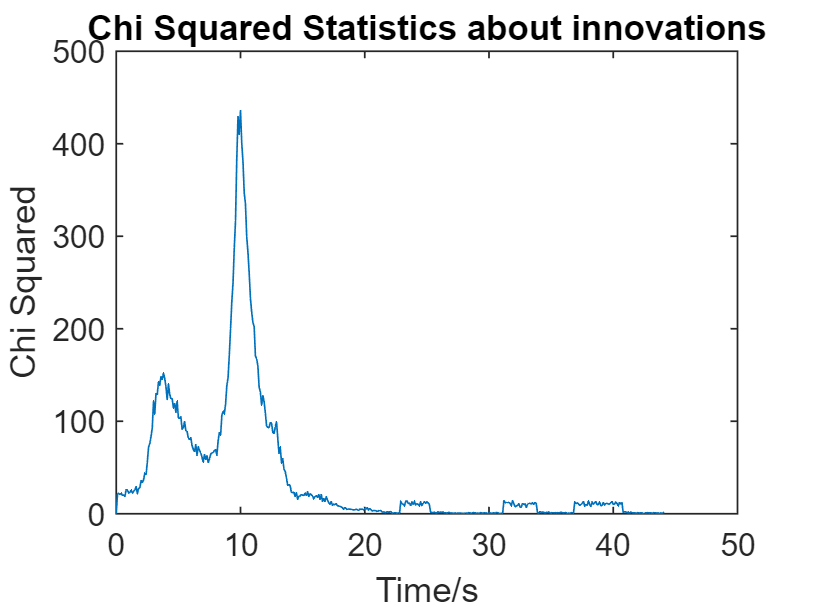


%chi-stat
plot(t, ChiStat);
xlabel('Time/s');
ylabel('Chi Squared');
title('Chi Squared Statistics about innovations');